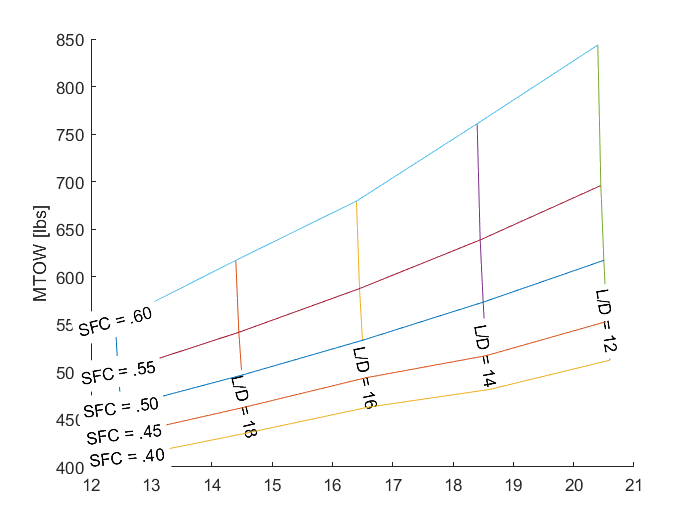

close all
clc
offset = 1;

% if( nargin < 5 )
%   nref = 0;
% end
% 
% % Handle default line styles.
% if( nargin < 6 )
%   linspec1 = 'k';
% end
% 
% if( nargin < 7 )
%   linspec2 = linspec1;
% end

% If input is not matrix similar to meshgrid, make it so.
if( isvector(x1) && isvector(x2) )
  [X1,X2] = meshgrid( x1, x2 );
else
  X1 = x1;
  X2 = x2;
end

% Calculate the cheater axis.
Xcheat = X1 + X2 * offset;

xc1 = Xcheat(1:0+1:end,:)';
yc1 = y(1:0+1:end,:)';

xc2 =  Xcheat(:,1:0+1:end);
yc2 = y(:,1:0+1:end);


figure
hold all
E5 = plot(xc1(1,:),yc1(1,:));
E4 = plot(xc1(2,:),yc1(2,:));
E3 = plot(xc1(3,:),yc1(3,:));
E2 = plot(xc1(4,:),yc1(4,:));
E1 = plot(xc1(5,:),yc1(5,:));
text2line(E1,.8,0,'L/D = 12')
text2line(E2,.8,0,'L/D = 14')
text2line(E3,.8,0,'L/D = 16')
text2line(E4,.8,0,'L/D = 18')
text2line(E5,.8,0,'L/D = 20')
c5 = plot(xc2(1,:),yc2(1,:));
c4 = plot(xc2(2,:),yc2(2,:));
c3 = plot(xc2(3,:),yc2(3,:));
c2 = plot(xc2(4,:),yc2(4,:));
c1 = plot(xc2(5,:),yc2(5,:));
text2line(c1,.2,0,'SFC = .40')
text2line(c2,.2,0,'SFC = .45')
text2line(c3,.2,0,'SFC = .50')
text2line(c4,.2,0,'SFC = .55')
text2line(c5,.2,0,'SFC = .60')
ylabel('MTOW [lbs]')






%h=carpet(x1,x2,y,1)